format long
syms d1 d2 d3 d4 d5 d6 
syms theta1 theta2 theta3 theta4 theta5 theta6 
syms theta_i theta_i_1 alpha_i_1 alpha_i d_i a_i_1
syms a1 a2 a3 a4 a5 a6
syms alpha1 alpha2 alpha3 alpha4 alpha5 alpha6
syms r11 r12 r13 r21 r22 r23 r31 r32 r33 Px Py Pz
syms T_i
%机器人学PUMA560机械臂参数

d1 = 0.03487*1000;
d2 = 0.01215*1000;
d3 = 0.1157*1000;
d4 = 0.000*1000;
d5 = 0.00717*1000;
d6 = 0.1256*1000;
%连杆长度
a0 = 0;
a1 = 0.000*1000;
a2 = 0.025*1000;
a3 = 0;
a4 = 0.059*1000;
a5 = 0;

%连杆长度

a11 = 0.002*1000;
a22 = 0.025*1000;
a33 = 0;
a44 = 0.059*1000;
a55 = 0;
a66 = 0;
%连杆扭角
alpha0 = 0;
alpha1 = pi/2;
alpha2 = -pi/2;
alpha3 = pi/2;
alpha4 = pi/2;
alpha5 = -pi/2;
alpha6 = 0;
% % 
% L1=Link([0     d1       a0       alpha0     ],'modified');%设置连杆参数，注：使用的是改进型DH参数，所以最后参数为'modified'
% L2=Link([0     d2       a1       alpha1     ],'modified');
% L3=Link([0     d3       a2       alpha2     ],'modified');
% L4=Link([0     d4       a3       alpha3     ],'modified');
% L5=Link([0     d5       a4       alpha4     ],'modified');
% L6=Link([0     d6       a5       alpha5     ],'modified');
% robot=SerialLink([L1 L2 L3 L4 L5 L6],'name','RobotArm');%将不同连杆链接起来

L1=Link([0     d1       a11        alpha1     ],'standard');%设置连杆参数，注：使用的是改进型DH参数，所以最后参数为'modified'
L2=Link([0     d2       a22        alpha2     ],'standard');
L3=Link([0     d3       a33        alpha3     ],'standard');
L4=Link([0     d4       a44       alpha4     ],'standard');
L5=Link([0     d5       a55       alpha5     ],'standard');
L6=Link([0     d6       a66       alpha6     ],'standard');
robot=SerialLink([L1 L2 L3 L4 L5 L6],'name','RobotArm');%将不同连杆链接起来

robot.plot([0,0,0,0,0,0]);%输出机器人模型，后面的六个角为输出时的theta姿态,用弧度制
robot.display();%打印出机器人D-H参数表

 
robot = 
 
RobotArm:: 6 axis, RRRRRR, stdDH, slowRNE                        
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      34.87|          2|     1.5708|          0|
|  2|         q2|      12.15|         25|    -1.5708|          0|
|  3|         q3|      115.7|          0|     1.5708|          0|
|  4|         q4|          0|         59|     1.5708|          0|
|  5|         q5|       7.17|          0|    -1.5708|          0|
|  6|         q6|      125.6|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


T=robot.fkine([0,0,0,0,0,0])%求机械臂正解

 

T = 
         1         0         0        86
         0         0        -1    -137.8
         0         1         0     143.4
         0         0         0         1


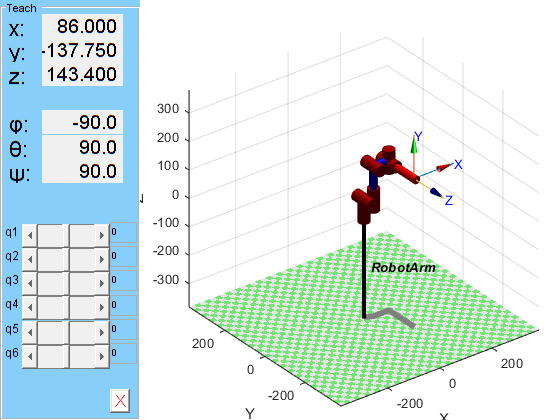

robot.teach( 'eul')%机械臂示教

% robot.ikine([ 1 1 1])
% R=[ cos(a)*cos(p) ,cos(a)*sin(p)*sin(r)-sin(a)*cos(r) , cos(a)*sin(p)*cos(r)+sin(a)*sin(r) ,X;
%     sin(a)*cos(p) ,sin(a)*sin(p)*sin(r)+cos(a)*cos(r) , sin(a)*sin(p)*cos(r)-cos(a)*sin(r) ,Y;
%     - sin(p)      , cos(p)*sin(r)                     ,cos(p)*sin(r)                       ,Z;
%     0 ,0,0,1;
%     ]
r=-90/180*pi;
p=90/180*pi;
a=90/180*pi;
X=86;
Y=-137.75;
Z=143.4;
R=[ cos(a)*cos(p) ,cos(a)*sin(p)*sin(r)-sin(a)*cos(r) , cos(a)*sin(p)*cos(r)+sin(a)*sin(r) ,X;
    sin(a)*cos(p) ,sin(a)*sin(p)*sin(r)+cos(a)*cos(r) , sin(a)*sin(p)*cos(r)-cos(a)*sin(r) ,Y;
    - sin(p)      , cos(p)*sin(r)                     ,cos(p)*sin(r)                       ,Z;
    0 ,0,0,1;
    ]

R = 1.0e+02 *

   0.000000000000000  -0.000000000000000  -0.010000000000000   0.860000000000000
   0.000000000000000  -0.010000000000000   0.000000000000000  -1.377500000000000
  -0.010000000000000  -0.000000000000000  -0.000000000000000   1.434000000000000
                   0                   0                   0   0.010000000000000


T1 = transl(  68 ,-83 ,168);

Inv_q=robot.ikine(T);
q1=Inv_q(1)*180/pi;
q2=Inv_q(2)*180/pi;
q3=Inv_q(3)*180/pi;
q4=Inv_q(4)*180/pi;
q5=Inv_q(5)*180/pi;
q6=Inv_q(6)*180/pi;
%使用改进型DH法，根据机器人学中对PUMA560机械臂建模方法实现运动学正解
q0=[ 0 0 0 00 -pi/2 0];

% L1.qlim =[0,180]/180*pi;
% L2.qlim =[0,180]/180*pi;
% L3.qlim =[0,360]/180*pi;
% L4.qlim =[]/180*pi;
% L5.qlim =[]/180*pi;  
% L6.qlim =[]/180*pi;
J0=robot.jacob0(q0)

J0 = 1.0e+02 *

   0.121500000000000  -1.085300000000000   0.000000000000000   0.071700000000000  -0.000000000000000                   0
   2.116000000000000   0.000000000000000   1.846000000000000   0.000000000000000  -1.256000000000000                   0
   0.000000000000000   2.096000000000000   0.000000000000000   1.846000000000000   0.000000000000000                   0
  -0.000000000000000                   0  -0.000000000000000                   0                   0   0.010000000000000
   0.000000000000000  -0.010000000000000   0.000000000000000  -0.010000000000000  -0.000000000000000  -0.000000000000000
   0.010000000000000   0.000000000000000   0.010000000000000   0.000000000000000  -0.010000000000000  -0.000000000000000


Je=robot.jacobe(q0)

Je = 1.0e+02 *

   2.116000000000000  -0.000000000000000   1.846000000000000  -0.000000000000000  -1.256000000000000                   0
   0.000000000000000   2.096000000000000   0.000000000000000   1.846000000000000                   0                   0
   0.121500000000000  -1.085300000000000  -0.000000000000000   0.071700000000000                   0                   0
  -0.000000000000000  -0.010000000000000  -0.000000000000000  -0.010000000000000                   0                   0
   0.010000000000000  -0.000000000000000   0.010000000000000  -0.000000000000000  -0.010000000000000                   0
  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000   0.000000000000000   0.010000000000000


T = robot.fkine(q0)

 

T = 
         0         0         1     211.6
         1         0         0    -12.15
         0         1         0     143.4
         0         0         0         1


r=t2r(T)

r =    0.000000000000000   0.000000000000000   1.000000000000000
   1.000000000000000   0.000000000000000  -0.000000000000000
  -0.000000000000000   1.000000000000000  -0.000000000000000


R = [ r zeros(3);
      zeros(3) r];
J1 = R*J0;
J2 = inv(R)*Je

J2 = 1.0e+02 *

   0.000000000000000   2.096000000000000   0.000000000000000   1.846000000000000  -0.000000000000000                   0
   0.121500000000000  -1.085300000000000   0.000000000000000   0.071700000000000  -0.000000000000000                   0
   2.116000000000000  -0.000000000000000   1.846000000000000  -0.000000000000000  -1.256000000000000                   0
   0.010000000000000  -0.000000000000000   0.010000000000000  -0.000000000000000  -0.010000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000  -0.000000000000000   0.010000000000000
  -0.000000000000000  -0.010000000000000  -0.000000000000000  -0.010000000000000   0.000000000000000  -0.000000000000000


J3 = R\Je

J3 = 1.0e+02 *

   0.000000000000000   2.096000000000000   0.000000000000000   1.846000000000000  -0.000000000000000                   0
   0.121500000000000  -1.085300000000000   0.000000000000000   0.071700000000000  -0.000000000000000                   0
   2.116000000000000  -0.000000000000000   1.846000000000000  -0.000000000000000  -1.256000000000000                   0
   0.010000000000000  -0.000000000000000   0.010000000000000  -0.000000000000000  -0.010000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000  -0.000000000000000   0.010000000000000
  -0.000000000000000  -0.010000000000000  -0.000000000000000  -0.010000000000000   0.000000000000000  -0.000000000000000


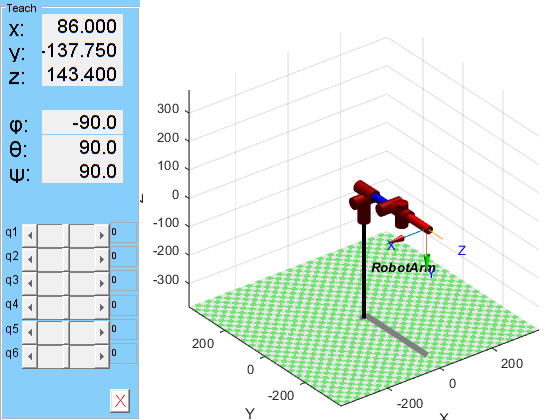

q1 =[pi/2 pi/2 0 pi/2 -pi/2 0];
t = 0:0.05:10;
[Q,dQ,ddQ] = jtraj(q0,q1,t);
robot.plot(Q);

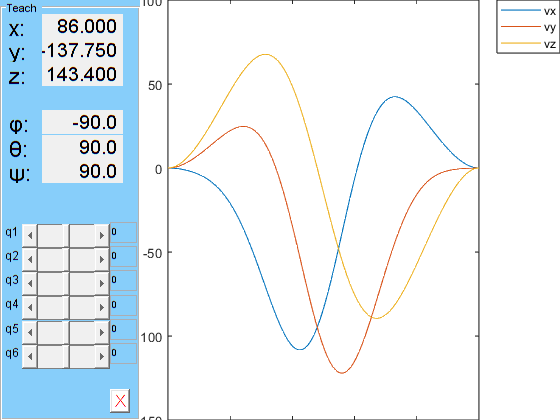

v=zeros(6,length(t));
for i=1:length(t)
    q=Q(i,:)';
    dq=dQ(i,:)';
    J0=robot.jacob0(q);
    v(:,i)=J0*dq;
end
plot(t,v(1:3,:)');
legend('vx','vy','vz');